clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',8);
set(0,'DefaultTextFontsize',8);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 10 3.5 3.5];
figpos = [0.34 0.27 0.6 0.6];

load("data\fig2_robot_test.mat");

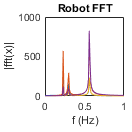

Y = fft(x_sin(:,1:end)');
L = size(Y,1);
Fs = 100;
x = Fs/L*(0:L-1);

xlimit = 1:1000;

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position', figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');
plot(x(xlimit),abs(Y(xlimit,:)));
xlim([0 1]);
ylabel("|fft(x)|");
xlabel("f (Hz)");
title("Robot FFT");


Yrob = abs(Y(xlimit,:))/max(abs(Y(xlimit,:)), [], "all");
Yrob_m = max(Yrob, [], 2);

load("data\fig2_fail_reservoir.mat");
% load("esnseed2\esn_No1.mat");

Y = fft(internalstatessin(1:end,:));
L = size(Y,1);
Fs = 100;
x = Fs/L*(0:L-1);

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position', figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');
plot(x(xlimit),abs(Y(xlimit,:)));
xlim([0 1]);
ylabel("|fft(S)|");
xlabel("f (Hz)");
title("Fail. Reservoir");

Yres = abs(Y(xlimit,:))/max(abs(Y(xlimit,:)), [], "all");
Yres_m = max(Yres, [], 2);
CR = sum(min(Yrob_m, Yres_m))/sum(Yrob_m);
disp(CR);

    0.3309



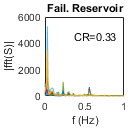

t = text(0.37, 4500, ['CR=' num2str(CR, '%.2f')]);

load("data\fig2_succ_reservoir.mat");
% load("esnseed2\esn_No5.mat");

Y = fft(internalstatessin(1:end,21:30));
L = size(Y,1);
Fs = 100;
x = Fs/L*(0:L-1);

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position', figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');
plot(x(xlimit),abs(Y(xlimit,:)));
xlim([0 1]);
ylabel("|fft(S)|");
xlabel("f (Hz)");
title("Succ. Reservoir");

Yres = abs(Y(xlimit,:))/max(abs(Y(xlimit,:)), [], "all");
Yres_m = max(Yres, [], 2);
CR = sum(min(Yrob_m, Yres_m))/sum(Yrob_m);
disp(CR);

    0.6774



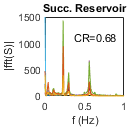

t = text(0.37, 1100, ['CR=' num2str(CR, '%.2f')]);

CRlist = [];

Nrlist = [10 20 50 500];
SRlist = [1.7 1.1 1.1 1.1];
for k = 2
Nr = Nrlist(k);
SR = SRlist(k);

for No = 1:100

    filename = ['esnseed\esn_Nr' num2str(Nr) 'SR' num2str(SR*10) 'No' num2str(No) '.mat'];
    load(filename, 'CR');
    CRlist = [CRlist; CR];
        
end
end

disp(mean(CRlist));

    0.5459



disp(var(CRlist));

    0.0321

